Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Koch's snowflake (Section 9.6)

Volker Ziemann, 211115, CC-BY-SA-4.0

The following code produces Koch's snowflake, and example of a geometric object with a fractal dimension, which is shown in Figure 9.6.

First we define the waiting_time in seconds to inspect each generation of the snowfalke, before it is replaced by the next generation. the checkbox allows us to follow the drawing of the snowflake in each generation, and max_generation specifies the number of iterations to zoom into the snowflake. Values latger than 5 or 6 may require some  patience, depending on the speed of the computer. 

%clear all
waiting_time=2;
show_meander=true;      % this also takes time
max_generation=4;      % maximum generations

Then we define the basic structure, sopecified by the array PP(), which defines a sequence of points. For Koch's snowflake we need four points that specify a triangle, where the first and last point agree.

PP=[-0.5,1/sqrt(3)-0.5*sqrt(3);
    0,1/sqrt(3);
    0.5,1/sqrt(3)-0.5*sqrt(3);
    -0.5,1/sqrt(3)-0.5*sqrt(3)];  % same as first

Now we are ready to iterate over the generations.  First figure out how many points are in the list of points PP, then allocate a new list PN, which will hold all points with the three additional ones due to the triangular detour in the middle of each straight line.

for generation=1:max_generation
    hold off
    plot(0,0)
    NN=size(PP,1);  % number of points , first=last
    PN=zeros(4*NN-3,2);

The following loop over all segments, labeled by m, we use the function nextpt(), defined in the appendix, to calculate the coordinates of the additional points and fills them into PN.

    for m=1:NN-1
        mm=4*m-3;
        PN(mm,:)=PP(m,:);
        PN(mm+1:mm+3,:)=nextpt(PP(m:m+1,:));
        PN(mm+4,:)=PP(m+1,:);
    end

At this point we could print the updated snowflake, but if the `show_meander `checkbox is selected, you can watch the snowflake being drawn. Don't do this if max_generation is larger than 4!

    if show_meander
      hold on
      for k=1:4*(NN-1)
        plot(PN(k:k+1,1),PN(k:k+1,2))
        axis equal 
        axis([-0.6 0.6 -0.6 0.6])
        pause(0.002)
      end
    end
    

Finally we display the finished snowflake in this generation and annotate the axis. 

    plot(PN(:,1),PN(:,2))
    axis equal 
    axis([-0.6 0.6 -0.6 0.6])
    title(['Generation:' num2str(generation) ...
        '     Num(vertices):' num2str(NN)]);

Before the next iteration we copy the new list of point PN to PP, which allows us to use the same code for the next iteration.

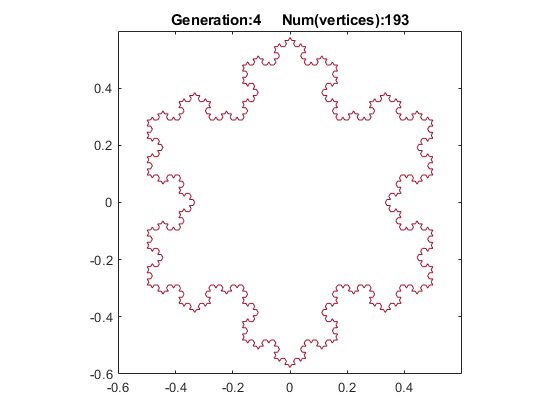

    PP=PN;
    pause(waiting_time)
end

clear PP PN   % cleanup memory

Having the finished snowflake ready, use MATLAB's zoom function to zoom into the edge an note that the triangular structure repeats up to the selected number of iterations.

Instead of using a triangle, you might also explore the objects that arise from replacing PP way up in the script by one of the following examples.

%...................................Line segment
% PP=[-0.5,0; 0.5,0];
%..................................Line both ways
% PP=[-0.5,0;   0.5,0; -0.5,0];
%........................................Square
% PP=[-0.25,-0.25; -0.25, 0.25; 0.25, 0.25; 0.25, -0.25; -0.25, -0.25];


## Appendix

The function nextpt() calculates the coordinates of the three additional points that come from the triangular detour in each line segment.

function PPP=nextpt(PP)
PPP=zeros(3,2);
PPP(1,:)=(2*PP(1,:)+PP(2,:))/3;
PPP(3,:)=(PP(1,:)+2*PP(2,:))/3;
DPP=PP(2,:)-PP(1,:);
PPP(2,:)=0.5*(PP(1,:)+PP(2,:))-[DPP(2),-DPP(1)]/(2*sqrt(3));
end